# Discriminant Analysis

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Load the pump features from `pumpFeatures.`

T = readtable("./data/pumpFeatures.csv");

Partition into training and testing

rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :)

dataTrain = 700×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean  

dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a discriminant analysis classifier, use the `fitcdiscr` function with the table as input and specify the name of the response variable. By default, the boundaries between classes are linear.

`discrModel` `=` `fitcdiscr``(``tableData``,``...`

    `"ResponseVariable"``)``;`

mdlDA = fitcdiscr(dataTrain, "faultCode");

Evaluate model

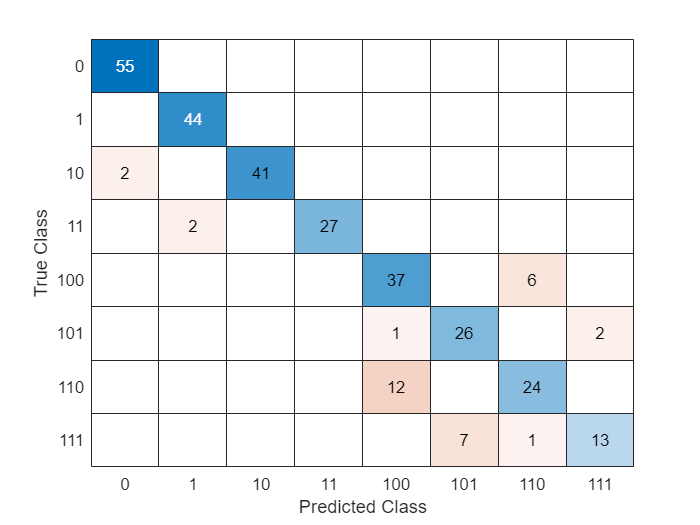

Training Error: 0.071429
Loss: 0.12122


evalModel(dataTest, mdlDA)

## Task 2

mdlDA = fitcdiscr(dataTrain, "faultCode", ...
    "DiscrimType", "diaglinear");

Evaluate model

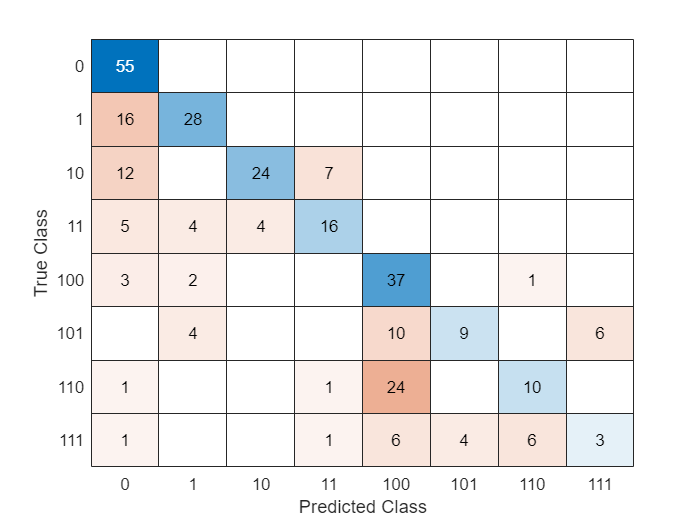

Training Error: 0.37571
Loss: 0.42412


evalModel(dataTest, mdlDA)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end